**INITIAL CLEARANCE OF THE WORKSPACE**

clear all;

**FILE IMPORT AND UNPACK**

% % load camera parameters
% LoadCameraParameters('./camera_parameters_lab.mat');
% 
% % read the image of the checkerboard
% image = imread('.\test images\checkerboard_lab_rgb.png');

camera = Camera3D('./camera_parameters_lab.mat');

ans =   cameraIntrinsics with properties:

             FocalLength: [925.9654 925.9056]
          PrincipalPoint: [641.6597 380.0837]
               ImageSize: [720 1280]
        RadialDistortion: [0.1506 -0.2320]
    TangentialDistortion: [0 0]
                    Skew: 0
                       K: [3×3 double]


Intel RealSense D435



% define the physical dimensions of a checkerboard square in millimeters.
edgeLength = 30;

% construct the 42 checkerboard points from points 1 and 6 in the rcs
% boardOriginRCS = [282.8  69.4]; % point 1 in rcs
% boardCornerRCS = [280.0 -81.9]; % point 6 in rcs
% boardOriginRCS = [310  76.35]; % point 1 in rcs
% boardCornerRCS = [311.93 -74.62]; % point 6 in rcs
boardOriginRCS = [305.11  82.61]; % point 1 in rcs
boardCornerRCS = [309.18 -68.09]; % point 6 in rcs


% [image, ~] = camera.snapshot();
% imwrite(image, "Testimage.png");

image = imread(".\test images\CaibrationImage.png");

transform = TransformPCStoCCS(image, camera.parameters, edgeLength);

ans = 1.0e+03 *

    0.7987    0.1970
    0.8217    0.2265
    0.8447    0.2557
    0.8678    0.2851
    0.8909    0.3146
    0.9142    0.3442
    0.9390    0.3750
    0.8284    0.1742
    0.8512    0.2036
    0.8741    0.2332


object =   TransformPCStoCCS with properties:

          dimensions: [7 7]
          edgeLength: 30
    cameraParameters: [1×1 cameraParameters]
          intrinsics: [1×1 cameraIntrinsics]
          extrinsics: []
    transformCCS2BCS: []
    transformBCS2RCS: []
           pointsPCS: [49×2 double]
           pointsBCS: [36×2 double]
           pointsCCS: [49×2 double]
           pointsRCS: []


Error using estimateExtrinsics
Expected imagePoints to be finite.

Error in vision.internal.inputValidation.validateExtrinsicsInputs (line 19)
validateattributes(imagePoints, {'double', 'single'}, ...

Error in 


transform.extendToRCS(boardOriginRCS, boardCornerRCS);

% define a set of pixel coordinates for testing
testPointsPCS = [camera.parameters.PrincipalPoint; 
    camera.parameters.PrincipalPoint + 150;
    0 0];

% apply full transformation on the testing set
testPointsRCS = transform.apply(testPointsPCS)
testDistances = norm(testPointsRCS(1, 1:2))

**VISUALIZATION**

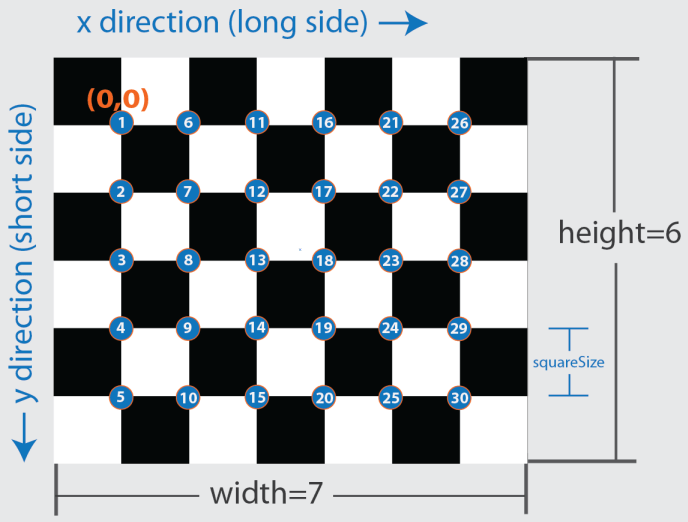

% display the image and plot the detected corners and axes
transform.show(image);